clc; clear all; close all;

Data = readtable("MA3231 final data - Sheet1.csv", "ReadVariableNames",true);


n = height(Data) - 1

n = 25


municipalities = table2array(Data(2:end, "municipality"));

populations = table2array(Data(2:end, "population"));
sum(populations)

ans = 2.7439e+03


incomes = table2array(Data(2:end,"medianIncome"));
homesales = table2array(Data(2:end,"monthlyHomeSales"));
homeprices = table2array(Data(2:end,"medianSalePrice"));

homeprices = homeprices * 0.75;

homesales = homesales * 0.26;

[Prog_no] = eligibility_script(homesales,homeprices, incomes);

affordability =     7.0647
    5.4189
    4.7191
    6.4463
    4.5321
    5.2889
    6.0182
    8.5259
    5.0335
    6.1602


inc = 141.3624

for i = 1:4
    eligible(i) = sum(Prog_no(i,:));
end

Budget = 1e7;

max_budget = 0.01 * 56e9; % cap at 1.5% of total mass annual budget (about 56 billion)

for n = 0:100
    Budget = n/100*max_budget /12; % slowly increase monthly budget up to 100% of max
    [temp1, temp2] = programsolver(Budget, eligible);
    obj(n+1) = temp1;
    results(:,n+1) = temp2(1:4);
    budj(n+1) = Budget;
end

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solu

optimal_idx = 50;

%find the index where the objective function levels off
for idx = 100:-1:2
    if(obj(idx-1) == obj(idx))
        optimal_idx = idx-1;
    end
end

obj(optimal_idx-1:optimal_idx+1); %confirm

sol = results(:, optimal_idx)

sol =   125.6512
   41.8837
  111.6899
         0



%monthly counts of people helped and budjet
(sol(1)+sol(2))*5e4 + (sol(3)+sol(4))*3e4

ans = 1.1727e+07

optimal_budj = budj(optimal_idx);
   

Pertown = distribute1(sol, Prog_no);

municipalities = table2array(Data(2:end, "municipality"));

HA_grants = table();
LA_grants = table();

n = size(Pertown, 2)

n = 25


for i = 1:n
    if Pertown(1, i) > 0
        new_row = [municipalities(i), Pertown(1,i), Pertown(2, i)];
        LA_grants = [LA_grants; new_row];
    end
    if Pertown(3, i) > 0
        new_row = [municipalities(i), Pertown(3,i), Pertown(4, i)];
        HA_grants = [HA_grants; new_row];
    end
end
vars = ["Municipality", "Low income" , "High income"];
HA_grants.Properties.VariableNames = vars;
LA_grants.Properties.VariableNames = vars;
HA_grants

HA_grants = 12×3 table
      Municipality       Low income    High income
    _________________    __________    ___________

    {'Worcester'    }        20             0     
    {'Springfield'  }        22             0     
    {'Lowell'       }         7             0     
    {'Brockton'     }         9             0     
    {'New Bedford'  }         7             0     
    {'Newton'       }         2             0     
    {'Framingham'   }         4             0     
    {'Haverhill'    }         6             0     
    {'Plymouth'     }        10             0     
    {'Taunton'      }         7             0     
    {'Weymouth Town'}         5             0     
    {'Chicopee'     }         5             0     


LA_grants

LA_grants = 13×3 table
     Municipality     Low income    High income
    ______________    __________    ___________

    {'Boston'    }        52            19     
    {'Cambridge' }         5             3     
    {'Quincy'    }         8             3     
    {'Lynn'      }         9             1     
    {'Fall River'}         9             1     
    {'Lawrence'  }         5             0     
    {'Somerville'}         7             1     
    {'Medford'   }         6             3     
    {'Malden'    }         4             1     
    {'Waltham'   }         3             1     
    {'Brookline' }         3             2     
    {'Revere'    }         3             0     
    {'Peabody'   }         5             0     


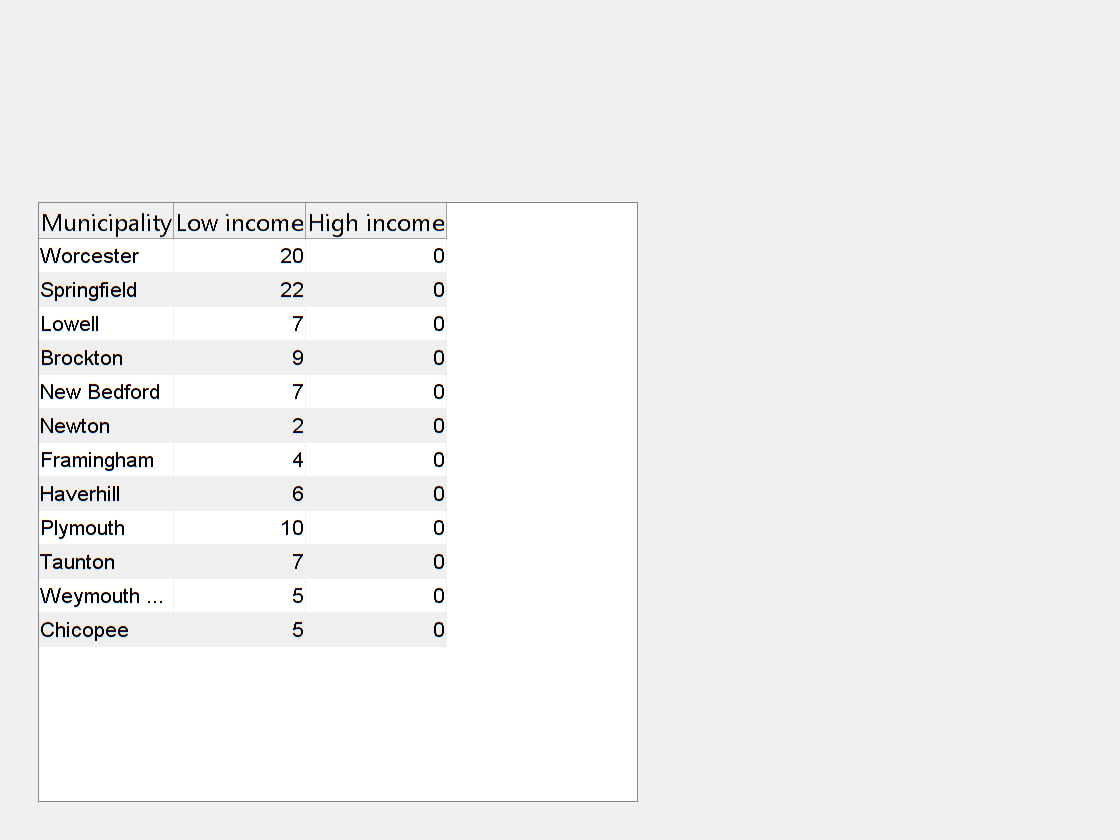


f = figure;
uit = uitable(f, 'Data', table2cell(HA_grants));
uit.ColumnName={HA_grants.Properties.VariableNames{:}}; %renaming columns to that of table
uit.RowName=[]; %removing default row numbering as in your uitable
saveas(f, 'HA_grants.png');

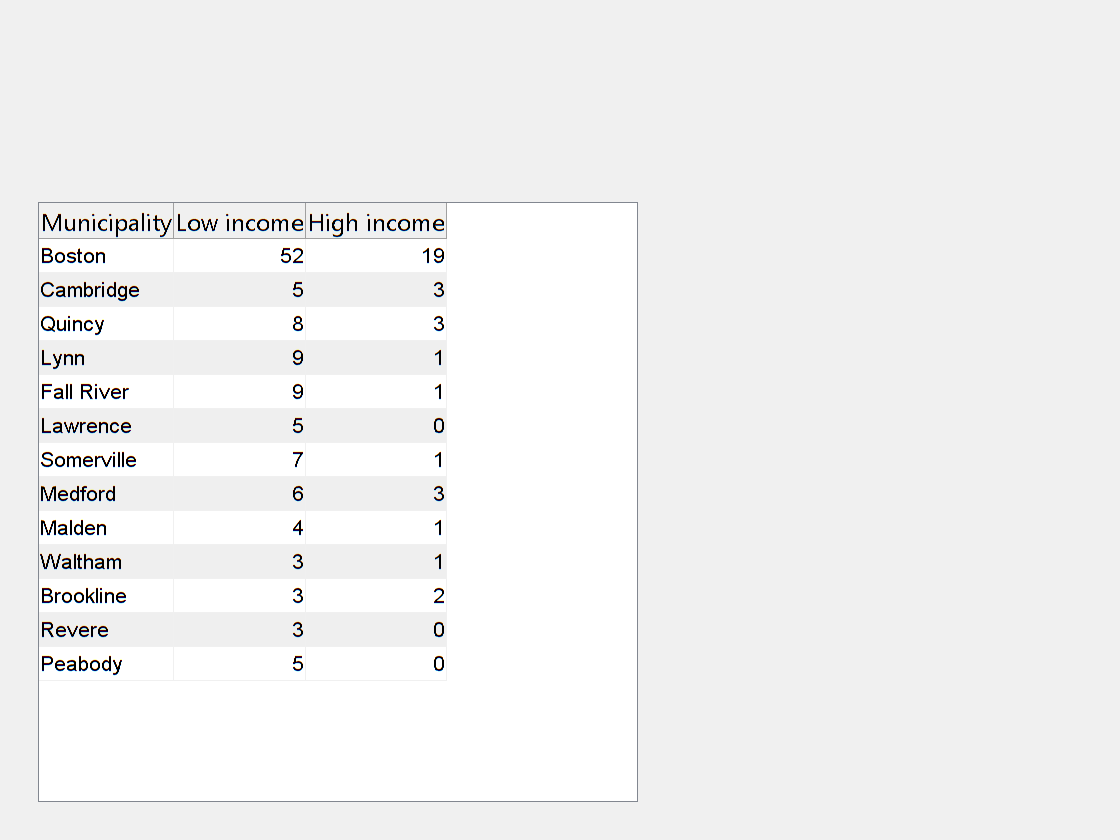


f = figure;
uit = uitable(f, 'Data', table2cell(LA_grants));
uit.ColumnName={LA_grants.Properties.VariableNames{:}};
uit.RowName=[];
saveas(f, 'LA_grants.png');